**Problem 1**

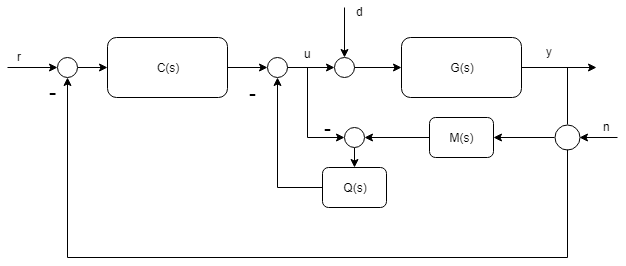

There are a couple of approaches you can take to block diagram algebra - a reductionist approach or a simple algebraic approach.  I'll do a mix.  The important thing to note is that for each transfer function we must assume all other inputs are zero.

Part a

For the sensitivity functions a simple approach is to find the equivalent plant $G^\star$that goes from the output of the feedback controller C(s) to the output y.  We have


$$Y = GU
$$



$$U = -Q(MY-U)+U_c = -(I-Q)^{-1}QMY+(I-Q)^{-1}U_c$$



$$\Rightarrow Y = -G(I-Q)^{-1}QMY+G(I-Q)^{-1}U_c$$


By invertibility of G we have


$$(I-Q)G^{-1}Y = -QMY+U_c$$



$$\Rightarrow G^\star = (G^{-1}+Q(M-G^{-1}))^{-1}$$


NOTE:  If $M = G^{-1}, G^\star = G$!

Given this result, we basically know the answers.  For the complementary sensitivity function we have


$$T = G^\star C(I+G^{\star}C)^{-1}$$


Similarly, we know that


$$S = (I+G^\star C)^{-1}$$


Part b

Here simple formulas will fail me, because the disturbance is entering inside of the equivalent plant.  So I'll revert to the algebraic approach.


$$Y = G(D+U) = GD-G(I-Q)^{-1}QMY-G(I-Q)^{-1}CY$$



$$\left((G^{-1}+Q(M-G^{-1})+C)\right)Y = (I-Q)D$$



$$\Rightarrow \frac{Y}{D} = \left((G^{-1}+Q(M-G^{-1})+C)\right)^{-1}(I-Q)$$


Now let's think about the design implications.  If $Q=I$, clearly the disturbance has no impact on the output - it is perfectly cancelled.  If $M = G^{-1}$ the equivalent plant is $G^\star = G$ and the design of the feedback controller is unaffected.  So why do we have $Q$?  Because $G^{-1}$ is often not realizable and is never fully known.  $Q$ is typically a low pass filter that is used to make $Q(M-G^{-1})\approx 0$ even at high frequencies where we cannot generate $G^{-1}$.

**Problem 2**

This is a standard problem in classical control.

Part a

The only nonlinearity in the system is due to $\sin\theta$.  Linearizing about $\theta = \frac{\pi}{2}$ we have


$$\sin\theta \approx \sin\frac{\pi}{2}+\cos\frac{\pi}{2}\delta\theta$$


where $\delta\theta$ is defined to be $\delta\theta = \theta-\frac{\pi}{2}
$.  The linearized differential equation is then


$$\ddot{\theta}+\frac{g}{l} = \frac{\tau}{ml^2}$$


Then, we define $\delta\tau$ as $\tau-\tau_0$ where $\tau_0=mgl$. $\delta\ddot\theta$ is simply $\ddot\theta$. The final linearized differential equation is then


$$\delta\ddot{\theta} = \frac{\delta\tau}{ml^2}$$


By performing Laplace transform, we can see the system has two poles at $s =0$, and hence the system is unstable at this configuration.

Part b

With the given values the plant transfer function becomes

G = tf(1/1/4^2,[1 0 0])

G =
 
  0.0625
  ------
   s^2
 
Continuous-time transfer function.



Now I need to find the desired pole locations from the specifications - thankfully there are formulas for those.

zeta = -log(.25)/sqrt(pi^2+(log(.25)^2))

zeta = 0.4037

w = 4/zeta/2

w = 4.9540

Given these values, I know that I want the denominator to look like $s^2+2\zeta\omega_ns+\omega_n^2$, with poles at 

roots([1 2*zeta*w w^2])

ans =   -2.0000 + 4.5324i
  -2.0000 - 4.5324i


Now lets look at the transfer function with a PD controller $C = k_p+k_ds$ applied.  I'll use $T = \frac{GC}{1+GC}$ to find the closed loop transfer function.


$$T = \frac{0.0625(k_p+k_ds)}{s^2+0.0625k_ds+0.0625k_p$$


Now it's simply a pattern matching problem...

kp = w^2/0.0625

kp = 392.6766

kd = 2*zeta*w/0.0625

kd = 64

Let's check if it worked.

C = tf([kd kp],1);
pole(feedback(G*C,1))

ans =   -2.0000 + 4.5324i
  -2.0000 - 4.5324i


Perfect!  Note that if I do the step response I did not quite make it.

stepinfo(feedback(G*C,1))

ans = struct with fields:
         RiseTime: 0.1990
    TransientTime: 1.9995
     SettlingTime: 1.9995
      SettlingMin: 0.9098
      SettlingMax: 1.3607
        Overshoot: 36.0717
       Undershoot: 0
             Peak: 1.3607
         PeakTime: 0.5066


The overshoot is bad but the settling time is OK.  After a little tweaking I got the following.

zeta = -log(.09)/sqrt(pi^2+(log(.09)^2))

zeta = 0.6083

w = 4/zeta/1.9

w = 3.4607

kp = w^2/0.0625

kp = 191.6230

kd = 2*zeta*w/0.0625

kd = 67.3684

C = tf([kd kp],1);
stepinfo(feedback(G*C,1))

ans = struct with fields:
         RiseTime: 0.2573
    TransientTime: 1.9499
     SettlingTime: 1.9499
      SettlingMin: 0.9063
      SettlingMax: 1.2451
        Overshoot: 24.5094
       Undershoot: 0
             Peak: 1.2451
         PeakTime: 0.6781


Looks pretty good!

Part C

The simulink model is included as a separate file.  Let me just run and print.

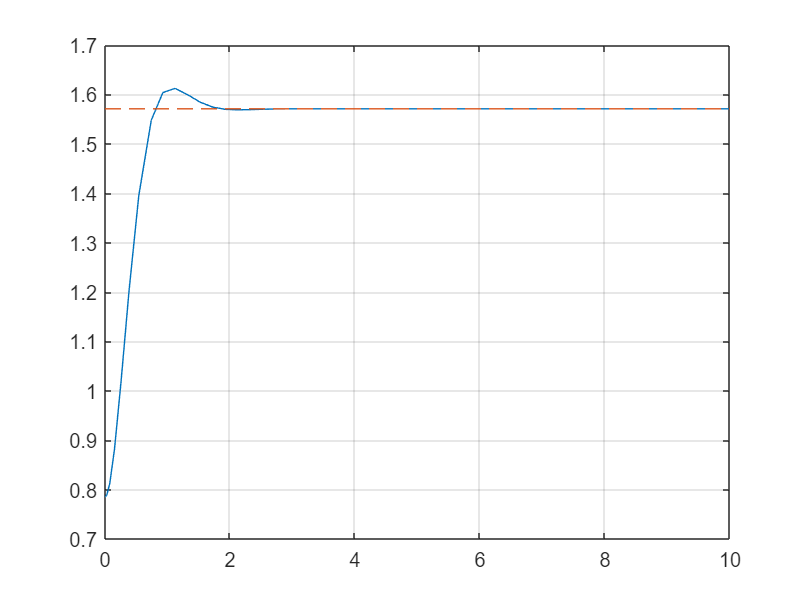

t0 = 45*pi/180;
sim('HW1_2c.slx');
plot(simout(:,1),simout(:,2), simout(:,1),pi/2*ones(1,length(simout(:,1))),'--')
grid

For this simple 2-pole system, a PD controller will always stabilize the system as long as it stabilizes it in the upright position.  It's not particularly hard to prove using the root locus (which I won't cover), but I'll just simulate to death.

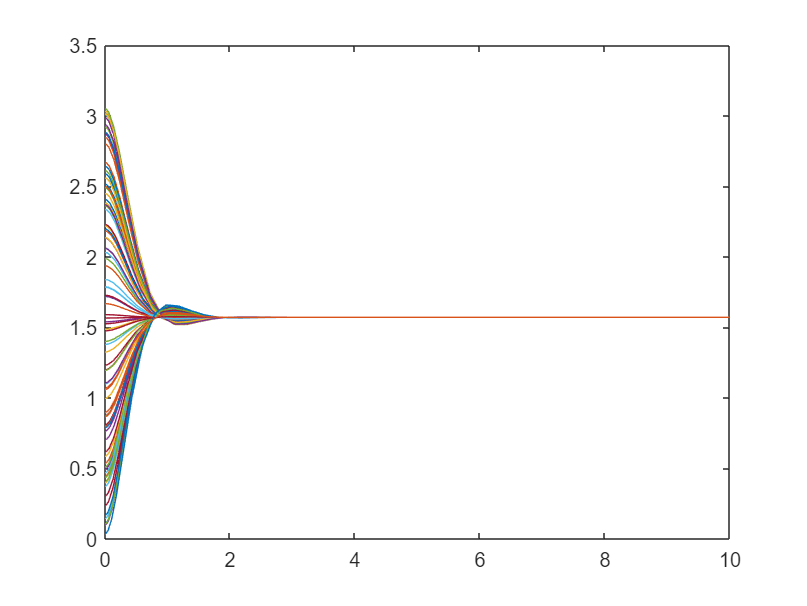

for ii = 1:100
    t0 = pi*rand;
    sim('HW1_2c');
    plot(simout(:,1),simout(:,2))
    hold on
end
hold off

**Problem 3**

This one is pretty quick and easy using Matlab.

Part a

A = [-3/4 -1/4;-1/2 -1/2];
B = [1;1];
C = [4 2];
rank(ctrb(A,B))

ans = 1

rank(obsv(A,C))

ans = 1

The observability and controllability matrices are both of rank 1, so the system is neither controllable nor observable.

Part b

I'm going to get a lot out of the next command:  find the minimal realization, then get its transfer function (for ease of controller design - could use state feedback I suppose).

G = tf(minreal(ss(A,B,C,[])))

1 state removed.

G =
 
    6
  -----
  s + 1
 
Continuous-time transfer function.



For a first order system, I can get any time constant I want with a proportional controller.  Right now the time constant is 1; standard form for a first order transfer function is $G = \frac{K}{\tau s+1}$.  With a proportional controller I would have the closed loop transfer function


$$T = \frac{6k_p}{s+1+6k_p}\Rightarrow \tau = \frac{1}{1+6k_p}$$


Therefore, substituting in the values, 

kp = (1/1e-3-1)/6

kp = 166.5000